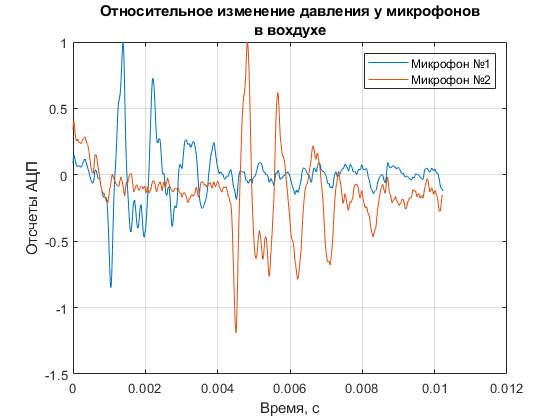

close all;
clear variables;

air0 = importdata('air.txt');
airRaw = air0.data;
breath0 = importdata("breath.txt");
breathRaw = breath0.data;
tt0 = importdata("totalTime.txt");


windowSize = 5;
b = (1 / windowSize) * ones(1, windowSize);
a = 1;

airFiltered = filter(b, a, airRaw());
breathFiltered = filter(b, a, breathRaw());

start = 30;

airFiltered = airFiltered(start:end, :);
breathFiltered = breathFiltered(start:end, :);
del = tt0.data / (size(airFiltered, 1) - 1) ; 
tt = 0 : del : tt0.data;

cAir = polyfit(tt', airFiltered(:, 1), 3);
cBreath = polyfit(tt', breathFiltered(:, 1), 3);

air = airFiltered - polyval(cAir, tt');
airNorm = air ./ max(air);

breath = breathFiltered - polyval(cBreath, tt');
breathNorm = breath ./ max(breath);

del = tt0.data / (size(airNorm, 1) - 1) ; 
time = 0 : del : tt0.data;

plot(tt', airNorm(:, 1), tt', airNorm(:, 2));
grid on;
title({'Относительное изменение давления у микрофонов', 'в вохдухе'});
xlabel('Время, с');
ylabel('Отсчеты АЦП');
legend('Микрофон №1', 'Микрофон №2');

disp([max(airNorm(:,1)),max(airNorm(:,2))])

  Column 1

     1

  Column 2

     1



index1 = find(airNorm(:,1) == 1);
index2 = find(airNorm(:,2) == 1);

deltaT1 = tt(index2) - tt(index1) %% время прохождения звуковой волны между микрофонами в воздухе

deltaT1 = 0.0034

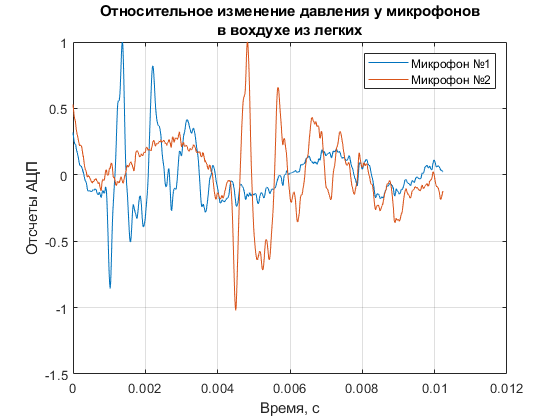





plot(tt', breathNorm(:, 1), tt', breathNorm(:, 2));
grid on;
title({'Относительное изменение давления у микрофонов', 'в вохдухе из легких'});
xlabel('Время, с');
ylabel('Отсчеты АЦП');
legend('Микрофон №1', 'Микрофон №2');

disp([max(breathNorm(:,1)),max(breathNorm(:,2))])

  Column 1

     1

  Column 2

     1



index1 = find(breathNorm(:,1) == 1);
index2 = find(breathNorm(:,2) == 1);

deltaT2 = tt(index2) - tt(index1) %% время прохождения звуковой волны между микрофонами в воздухе из легких

deltaT2 = 0.0035


%% данные из таблицы в методичке
Ma = 28.97;%%мю смеси газов
Mw = 18.01;%% мю воды
Mco2 = 44.01;%% мю со2
Cpa = 1.0036; %%Ср
Cpw = 1.863;
Cpco2 = 0.838;
Cva = 0.7166;%% С ню
Cvw = 1.403;
Cvco2 = 0.649;
Xw = importdata('volumeFractionWater.txt');%% кол-во в-ва
T = importdata('temperature.txt'); %% температура в цельсиях
R = 8314; %% газовая постоянная
S = 1.158; %% расстояние между микрофонами
Xco2 = 0.03;
Xa = 1 - Xco2 - Xw.data; 

M = Ma*Xa + Mw*Xw.data + Mco2*Xco2;%% мю
G = (Ma*Xa*Cpa + Mw*Xw.data*Cpw + Mco2*Xco2*Cpco2) / (Ma*Xa*Cva + Mw*Xw.data*Cvw + Mco2*Xco2*Cvco2); %%гамма

Speed1 = sqrt(G * R * (T.data + 273) / M); %% по формуле из методички
disp(['Расчетная скорость звука в воздухе: Speed1 = ', num2str(Speed1), ' м/с']);

Расчетная скорость звука в воздухе: Speed1 = 342.3332 м/с


dt1 = S / Speed1; %% расчетное время



Speed2 = S / deltaT2;  %%экспериментальная скросость звука в воздухе из легких
disp(['Скорость звука в воздухе из легких: Speed1 = ', num2str(Speed2), ' м/с']);

Скорость звука в воздухе из легких: Speed1 = 334.8729 м/с


Speed22.v = zeros(1000);
Speed22.i = zeros(1000);


%% подбираем значение дельта x - на скалько изменилась объемная доля СО2
for  x = 1  : 1 : 1000
    G1 = (Ma*(1 - Xw.data - x/1000)*Cpa + Mw*Xw.data*Cpw + Mco2*(x/1000)*Cpco2) / (Ma*(1 - Xw.data - x/1000)*Cva + Mw*Xw.data*Cvw + Mco2*(x/1000)*Cvco2);
M1 = Ma*(1- Xw.data - x/1000) + Mw*Xw.data + Mco2*(x/1000);
       Speed22.v(x) = sqrt(G1 * R * (T.data + 273) / M1);
        Speed22.i(x) = x/1000;
end

for  x = 1 : 1000
    dS.v(x) = abs(Speed22.v(x) - Speed2);
    dS.i(x) = x/1000;
end

ind = find(dS.v == min(dS.v));
Xco2breath = dS.i(ind)

Xco2breath = 0.1030


disp(['Объёмная доля углекислого газа в воздухе из лекгих: Xco2(breath) = ', num2str(Xco2breath)])

Объёмная доля углекислого газа в воздухе из лекгих: Xco2(breath) = 0.103




speed = Speed22.v'

speed =   345.4452  345.3366  345.2281  345.1197  345.0114  344.9032  344.7950  344.6870  344.5790  344.4712  344.3634  344.2557  344.1481  344.0407  343.9333  343.8259  343.7187  343.6116  343.5046  343.3976  343.2908  343.1840  343.0773  342.9708  342.8643  342.7579  342.6515  342.5453  342.4392  342.3332  342.2272  342.1213  342.0156  341.9099  341.8043  341.6988  341.5934  341.4880  341.3828  341.2776  341.1726  341.0676  340.9627  340.8579  340.7532  340.6486  340.5440  340.4396  340.3352  340.2310
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

speed0 = ones(1000)

speed0 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

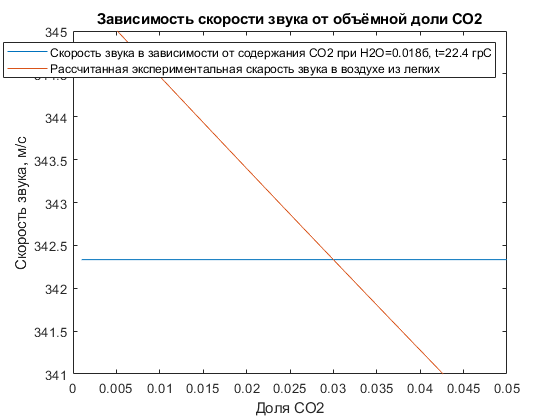

yy = speed0.*Speed1;
xx = 1 : 1 : 1000;
xx0 = xx./1000;
plot(xx0, yy(1,:), xx0, speed(1,:));
xlim([0 0.05]);
ylim([341 345]);
xlabel('Доля СО2');
ylabel('Скорость звука, м/с');
legend('Скорость звука в зависимости от содержания СО2 при Н2О=0.018б, t=22.4 грС', 'Рассчитанная экспериментальная скарость звука в воздухе из легких');
title('Зависимость скорости звука от объёмной доли СО2');